waveinfo('cmor');

 Information on complex Morlet wavelet.
 
    Complex Morlet Wavelet
 
    Definition: a complex Morlet wavelet is
        cmor(x) = (pi*Fb)^{-0.5}*exp(2*i*pi*Fc*x)*exp(-(x^2)/Fb)
    depending on two parameters:
        Fb is a bandwidth parameter
        Fc is a wavelet center frequency
 
    Family                  Complex Morlet
    Short name              cmor
 
    Wavelet name            cmor"Fb"-"Fc"
 
    Orthogonal              no
    Biorthogonal            no
    Compact support         no
    DWT                     no
    complex CWT             possible
 
    Support width           infinite
 
    Reference: A. Teolis, 
    Computational signal processing with wavelets, 
    Birkhauser, 1998, 65.



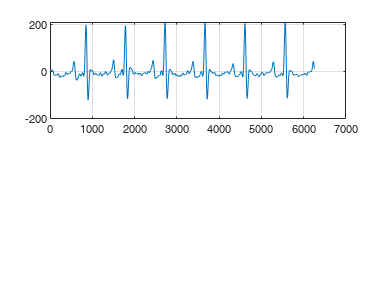

[y,fs] = audioread("C:\Users\Евгений\PycharmProjects\pythonProject\source\Фильтрованные\4\НЧ\2.wav");
figure();
subplot(2,1,1);
plot(y(6250:12500));
grid("on");

wt=cwt(y(6250:12500),'bump');
cwtftinfo();

 cwtftinfo Information on wavelets for CWTFT
  cwtftinfo provides information on the available wavelets for 
  Continuous Wavelet Transform using FFT.
 
    PSI_HAT denotes the Fourier transform of the wavelet.
 
    Morlet: 
      'morl':
        PSI_HAT(k) = pi^(-1/4)exp(-(k-k0)^2/2)H(k) where H(k) is the
        Heaviside function.
        Parameter: k0, default k0 = 6. 
        k0 is the center frequency in radians/sample. The center frequency 
        cycles/sample is k0/(2*pi).       
 
      'morlex': (without Heaviside function)
        PSI_HAT(k) = pi^(-1/4)exp(-(k-k0)^2/2)
        Parameter: k0, default k0 = 6. 
        k0 is the center frequency in radians/sample. The center frequency 
        in cycles/sample is k0/(2*pi).
 
      'morl0':  (with exact zero mean value)
        PSI_HAT(k) = pi^(-1/4) [exp(-(k-k0)^2/2) - exp(k0^2/2)]
        Parameter: k0, default k0 = 6. 
        k0 is the center frequency in
        radians/sample. The cent

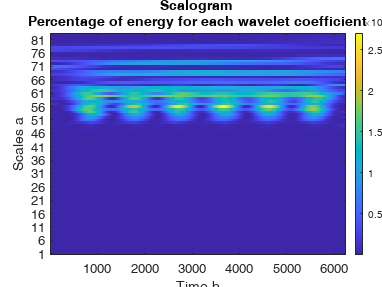

wscalogram('image',wt);

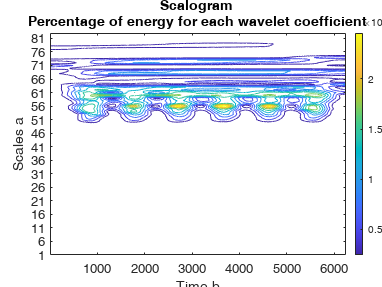

wscalogram('contour',wt);

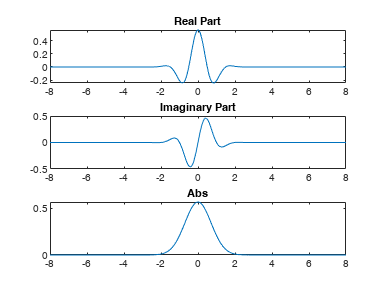

wtf=cwtft(y(6250:12500),'wavelet','paul');
N = 1000;
Lb = -8;
Ub = 8;
fb = 1.5;
fc = 1;
[psi,x] = cmorwavf(-8,8,1000,1.0,0.5);
figure();
subplot(3,1,1)
plot(x,real(psi)); title('Real Part');
subplot(3,1,2)
plot(x,imag(psi)); title('Imaginary Part');
subplot(3,1,3)
plot(x,abs(psi)); title('Abs');

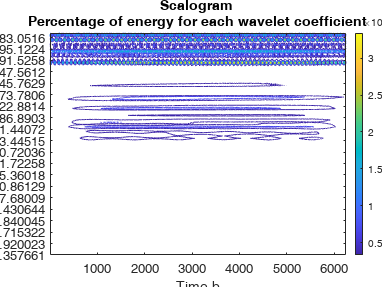

wavename='cmor1-0.5';
wcf=centfrq(wavename); %Center Frequency of Wavelet
scal=fs*wcf./f;%Using frequency conversion scales
figure();
t=linspace(0,2,6251);
sc=wscalogram('contour',coefs,scal);

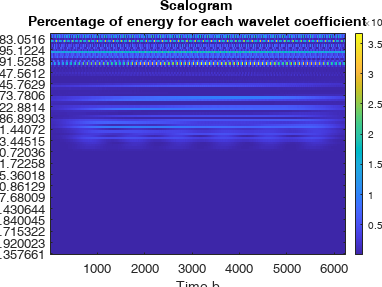

sc=wscalogram('image',coefs,scal);

F = scal2frq(scal,wavename,0.001);


